Problem 1:

clear all

q=1;
dt=0.1;
s=0.5;
m0=[0;0;1;-1];
P0=eye(4);
A=kron([1,dt;0,1],eye(2));
Q=q*kron([dt^3/3,dt^2/2;dt^2/2,dt],eye(2));
H=kron([1,0],eye(2));
R=s^2*eye(2);
X0=m0;           % true initial state

%
% Generate a track and measurements
%
nx=size(Q,1); ny=size(R,1);
nk=100;
X=zeros(nx,nk);
Y=zeros(ny,nk);
x=X0;
rng(33,'v5normal')   % use the legacy generator to replicate Figure 4.5
for k=1:nk
    x=mvnrnd(A*x,Q)';
    y=mvnrnd(H*x,R)';
    X(:,k)=x;
    Y(:,k)=y;
end

%
% Kalman filter
%
kf_m=zeros(nx,nk); 
m=m0; P=P0;
for k=1:nk
    [m,P]=kf_predict(m,P,A,Q);
    [m,P]=kf_update(m,P,Y(:,k),H,R);
    kf_m(:,k)=m;
 end

%
% RTS fixed-interval smoother
%
rts_m=zeros(nx,nk); 
rts_e=zeros(1,nk);
kf_e=zeros(1,nk);
kf_m=zeros(nx,nk);
kf_P=zeros(nx,nx,nk);
m=m0; P=P0;
for k=1:nk % forward pass, Kalman filter (same as above)
    [m,P]=kf_predict(m,P,A,Q);
    [m,P]=kf_update(m,P,Y(:,k),H,R);
    kf_m(:,k)=m;
    kf_P(:,:,k)=P;
    kf_e(k)=trace(P);
end

%Compute stationary G
XX=dare(A',H',Q,R);
S=H*XX*H'+R;
K=XX*H'/S;
P=XX-K*S*K';
G=P*A'/XX;

% backward pass, stationary
rts_m(:,end)=m; rts_e(end)=trace(P);
for k=nk-1:-1:1
    [mp,Pp]=kf_predict(kf_m(:,k),kf_P(:,:,k),A,Q);
    
    m=kf_m(:,k)+G*(m-mp);
    P=kf_P(:,:,k)+G*(P-Pp)*G'; 
    rts_m(:,k)=m;
    rts_e(k)=trace(P); 
end

rmse_rts=sqrt(mean(sum((rts_m(1:2,:)-X(1:2,:)).^2,1)))

rmse_rts = 0.2549

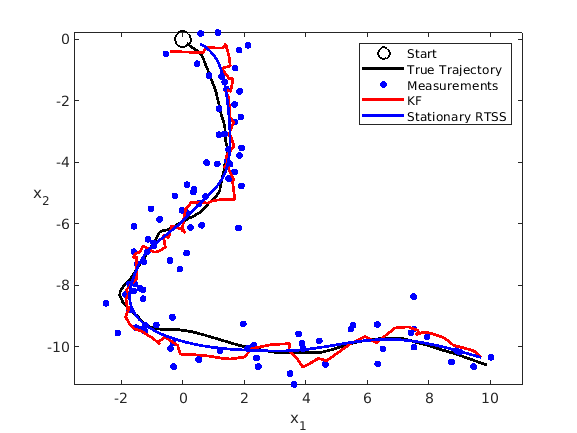


figure, clf
plot(m0(1),m0(2),'ko',X(1,:),X(2,:),'k-',Y(1,:),Y(2,:),'b.',...
    kf_m(1,:),kf_m(2,:),'r-',rts_m(1,:),rts_m(2,:),'b-',...
    'linewidth',2,'markersize',12);
legend('Start','True Trajectory','Measurements','KF','Stationary RTSS');
xlabel('x_1'); ylabel('x_2','rot',0); axis equal

Problem 2:

clear all;

% Define simulation parameters
rng('default'); rng(0) % set the random number generator's starting value
g=9.81;        % gravity acceleration constant
qc=1;          % power spectral density of white noise excitation
r=0.1;         % measurement noise variance
x0=[1.5;0];    % initial state (radian angle and angular velocity)
DT=0.01;       % time step size
nk=500;        % number of steps

% Generate the track and the measurements
T=(1:nk)*DT;   % timestamps
X=zeros(1,nk); % preallocate
Y=NaN(1,nk);   % preallocate using not-a-number
x=x0;
m=5;           % number of time steps per measurement
for k=1:nk
    x=x+DT*[x(2);-g*sin(x(1))]+[0;sqrt(qc*DT)*randn];
    if ~rem(k,m)
        Y(k)=sin(x(1))+sqrt(r)*randn;
    end
    X(k)=x(1);
end

% Define some common filter parameters
m0 = [1.6;0];       % slightly off from x0
P0 = 0.1*eye(2);
Q=[0 0;0 qc*DT];
R=r;
nx=size(Q,1);

nlags = [1,3,10,50,100];
for new_nlag = 1:5
    nlag = nlags(new_nlag)
    
    fls_m=zeros(nx,nk-nlag+1);  % fls_m(:,k+1) = the mean of x_k | y_{1:k+nlag}
    mStack=zeros(nx,nlag); mpStack=zeros(nx,nlag); Gstack=zeros(nx,nx,nlag);
    m=m0; P=P0;

    %predict
    [mp,Pp,D] = GaussApproxEKF(m,P,@pendulum_f,Q);
    mStack(:,1)=m; mpStack(:,1)=mp; Gstack(:,:,1)=D/Pp;

    for k=1:nk
        %update
        [m,P]=gf_update(mp,Pp,Y(k),@pendulum_h,R,@GaussApproxEKF);
        if k>=nlag  % process the stack with RTSS 
            mm=m;
            for j=1:nlag
                mm=mStack(:,j)+Gstack(:,:,j)*(mm-mpStack(:,j));
            end
            fls_m(:,k-nlag+1)=mm;
        end
    
        %predict
        [mp,Pp,Dd] = GaussApproxEKF(m,P,@pendulum_f,Q);
    
        % update the stacks
        mStack(:,2:nlag)=mStack(:,1:nlag-1); mStack(:,1)=m;
        mpStack(:,2:nlag)=mpStack(:,1:nlag-1); mpStack(:,1)=mp;
        Gstack(:,:,2:nlag)=Gstack(:,:,1:nlag-1); Gstack(:,:,1)=Dd/Pp;
    end

    %rmse
    rmse_fls=sqrt(mean(sum((fls_m(1,:)-[x0(1) X(1,1:nk-nlag)]).^2,1)))
end

nlag = 1

rmse_fls = 0.1779

nlag = 3

rmse_fls = 0.1743

nlag = 10

rmse_fls = 0.1638

nlag = 50

rmse_fls = 0.1522

nlag = 100

rmse_fls = 0.1359

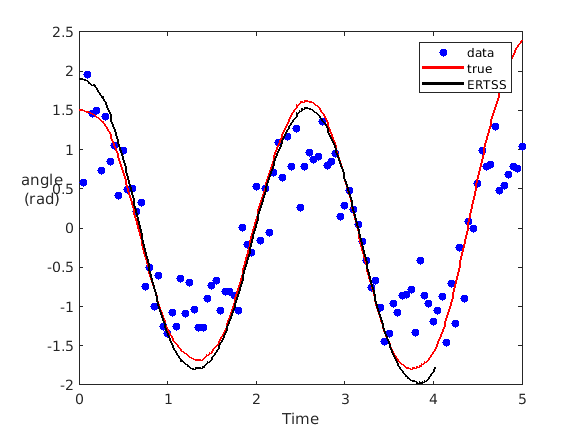



%plot
figure
plot(T,Y,'b.', [0,T],[x0(1),X(1,:)],'r-'...
    ,T(1:nk-nlag+1),fls_m(1,:),'k-','linewidth',2,'markersize',20)
xlabel('Time')
ylabel({'angle';'(rad)'},'rot',0)
legend('data','true','ERTSS')


%seems that bigger nlag produces better smoothing results.

Problem 3:

clear all

% Define simulation parameters
rng('default'); rng(0) % set the random number generator's starting value
g=9.81;        % gravity acceleration constant
qc=1;          % power spectral density of white noise excitation
r=0.1;         % measurement noise variance
x0=[1.5;0];    % initial state (radian angle and angular velocity)
DT=0.01;       % time step size
nk=500;        % number of steps

% Generate the track and the measurements
T=(1:nk)*DT;   % timestamps
X=zeros(1,nk); % preallocate
Y=NaN(1,nk);   % preallocate using not-a-number
x=x0;
m=5;           % number of time steps per measurement
for k=1:nk
    x=x+DT*[x(2);-g*sin(x(1))]+[0;sqrt(qc*DT)*randn];
    if ~rem(k,m)
        Y(k)=sin(x(1))+sqrt(r)*randn;
    end
    X(k)=x(1);
end

% Define some common filter parameters
m0 = [1.6;0];       % slightly off from x0
P0 = 0.1*eye(2);
Q=[0 0;0 qc*DT];
R=r;

% Run the filters
filtername={'UKF'};                   % *** CHANGED ***
GA={@GaussApproxUKF};       % *** CHANGED ***
nf=length(filtername);
M1f=zeros(nf,nk);     M1s = zeros(nf,nk);
Pf=zeros(2,2,nk);
Mf=zeros(2,nk);
for jf=1:nf
    m=m0; P=P0;
    for k=1:nk   % forward sweep (filter)
        [m,P]=gf_predict(m,P,@pendulum_f_vectorized,Q,GA{jf});
        [m,P]=gf_update(m,P,Y(k),@pendulum_h_vectorized,R,GA{jf});
        M1f(jf,k)=m(1);
        Mf(:,k)=m; Pf(:,:,k)=P;
    end
    rmse=sqrt(mean((X(1,:)-M1f(jf,:)).^2));
    disp(['RMS error for filter ' num2str(jf) ' is ' num2str(rmse)])
    
    M1s(jf,end)=m(1);
    for k=nk-1:-1:1  % backward sweep (smoother)
        [mp,Pp,Dk]=GA{jf}(Mf(:,k),Pf(:,:,k),@pendulum_f_vectorized,Q);
        Gk=Dk/Pp;
        m=Mf(:,k)+Gk*(m-mp);
        P=Pf(:,:,k)+Gk*(P-Pp)*Gk';
        M1s(jf,k)=m(1);
    end
    % one more backward step to estimate initial state
    [mp,Pp,D0]=GA{jf}(m0,P0,@pendulum_f_vectorized,Q); G0=D0/Pp;
    m=m0+G0*(m-mp); M1s0(jf)=m(1);
    rmse=sqrt(mean((X(1,:)-M1s(jf,:)).^2));
    disp(['RMS error for smoother ' num2str(jf) ' is ' num2str(rmse)])
end

RMS error for filter 1 is 0.23629


RMS error for smoother 1 is 0.12096


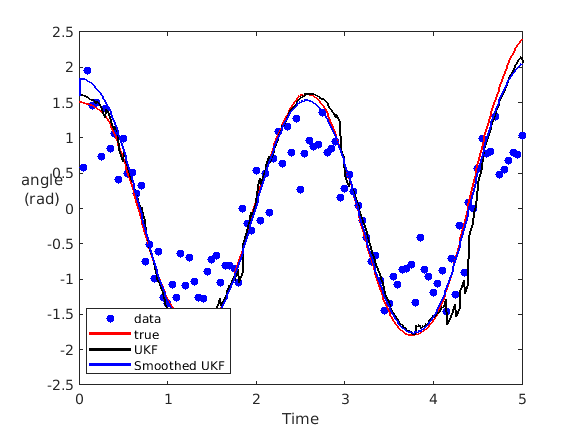


% Plot the results
plot(T,Y,'b.', ...
    [0,T],[x0(1),X(1,:)],'r-',...
    [0,T],[m0(1),M1f(1,:)],'k-',...
    [0,T],[m0(1),M1s(1,:)],'b-','linewidth',2,'markersize',20);
xlabel('Time')
ylabel({'angle';'(rad)'},'rot',0)
legend('data','true','UKF','Smoothed UKF','location','SW')

Problem 4:

clear all

rng('default'); rng(0) % set the random number generator's starting value
g=9.81;        % gravity acceleration constant
qc=1;          % power spectral density of white noise excitation
r=0.1;         % measurement noise variance
x0=[1.5;0];    % initial state (radian angle and angular velocity)
DT=0.01;       % time step size
nk=500;        % number of steps
T=(1:nk)*DT;   % timestamps
X=zeros(1,nk); % preallocate
Y=NaN(1,nk);   % preallocate using not-a-number
m=5;           % number of time steps per measurement

u=x0(1); v=x0(2);
for k=1:nk
    u=u+DT/2*v; 
    v=v-g*DT*sin(u)+randn*sqrt(qc*DT);
    u=u+DT/2*v;
    if ~rem(k,m)
        Y(k)=sin(u)+sqrt(r)*randn;
    end
    X(k)=u;
end

%filter
m0=[1.6;0];    
P0=0.1*eye(2);
Q=qc*[DT^3/4, DT^2/2; DT^2/2, DT];   % *** CHANGED ***
R=r;

filtername={'EKF','EKF2'};
GA={@GaussApproxEKF,@GaussApproxEKF2};
nf=length(filtername);
M1f=zeros(nf,nk);     M1s = zeros(nf,nk);
Mf=zeros(2,nk); Pf=zeros(2,2,nk);   % save for the smoother
for jf=1:nf
    m=m0; P=P0;
    for k=1:nk   % forward sweep (filter)
        [m,P]=gf_predict(m,P,@pendulum_f_leapfrog,Q,GA{jf});
        [m,P]=gf_update(m,P,Y(k),@pendulum_h,R,GA{jf});
        M1f(jf,k)=m(1);
        Mf(:,k)=m; Pf(:,:,k)=P;
    end
    rmse=sqrt(mean((X(1,:)-M1f(jf,:)).^2));
    disp(['RMS error for filter ' num2str(jf) ' is ' num2str(rmse)])
    
    M1s(jf,end)=m(1);
    for k=nk-1:-1:1  % backward sweep (smoother)
        [mp,Pp,Dk]=GA{jf}(Mf(:,k),Pf(:,:,k),@pendulum_f_leapfrog,Q);
        Gk=Dk/Pp;
        m=Mf(:,k)+Gk*(m-mp);
        P=Pf(:,:,k)+Gk*(P-Pp)*Gk';
        M1s(jf,k)=m(1);
    end
    % one more backward step to estimate initial state
    [mp,Pp,D0]=GA{jf}(m0,P0,@pendulum_f_leapfrog,Q); G0=D0/Pp;
    m=m0+G0*(m-mp); M1s0(jf)=m(1);
    rmse=sqrt(mean((X(1,:)-M1s(jf,:)).^2));
    disp(['RMS error for smoother ' num2str(jf) ' is ' num2str(rmse)])
end

RMS error for filter 1 is 0.19205


RMS error for smoother 1 is 0.16422


RMS error for filter 2 is 0.16762


RMS error for smoother 2 is 0.15896


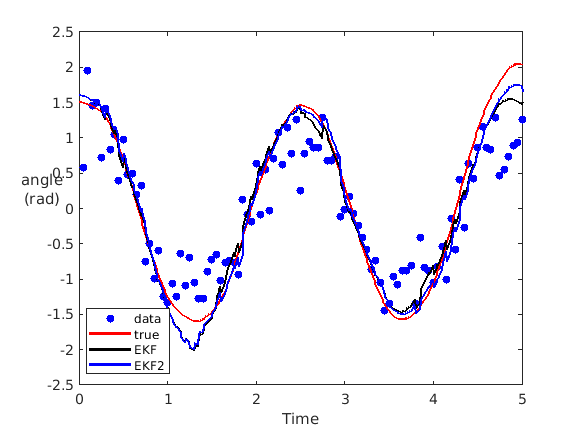


%plot results
figure
plot(T,Y,'b.', ...
    [0,T],[x0(1),X(1,:)],'r-',...
    [0,T],[m0(1),M1f(1,:)],'k-',...
    [0,T],[m0(1),M1f(2,:)],'b-','linewidth',2,'markersize',20);
xlabel('Time')
ylabel({'angle';'(rad)'},'rot',0)
legend('data','true',filtername{1},filtername{2},'location','SW')

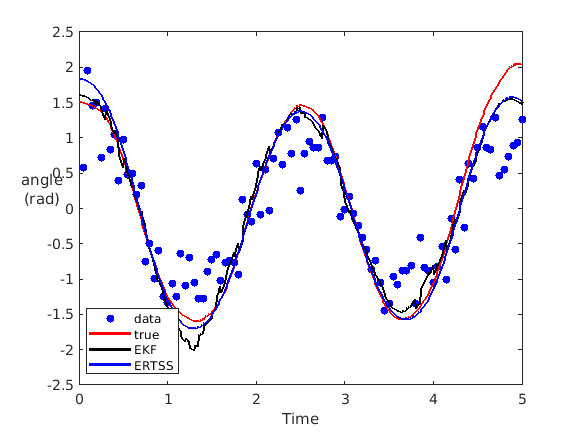


figure
plot(T,Y,'b.', ...
    [0,T],[x0(1),X(1,:)],'r-',...
    [0,T],[m0(1),M1f(1,:)],'k-',...
    [0,T],[M1s0(1),M1s(1,:)],'b-','linewidth',2,'markersize',20);
xlabel('Time')
ylabel({'angle';'(rad)'},'rot',0)
legend('data','true','EKF','ERTSS','location','SW')

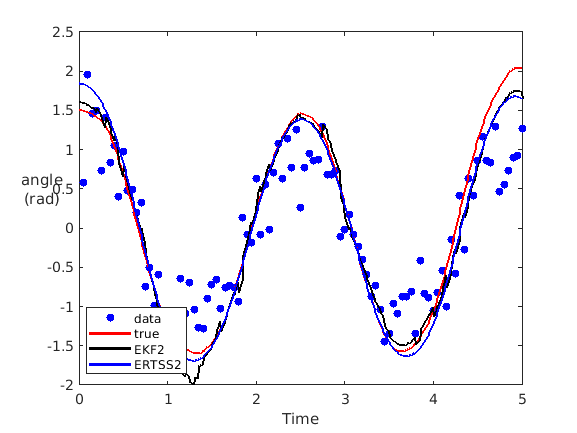


figure
plot(T,Y,'b.', ...
    [0,T],[x0(1),X(1,:)],'r-',...
    [0,T],[m0(1),M1f(2,:)],'k-',...
    [0,T],[M1s0(1),M1s(2,:)],'b-','linewidth',2,'markersize',20);
xlabel('Time')
ylabel({'angle';'(rad)'},'rot',0)
legend('data','true','EKF2','ERTSS2','location','SW')

Problem 5

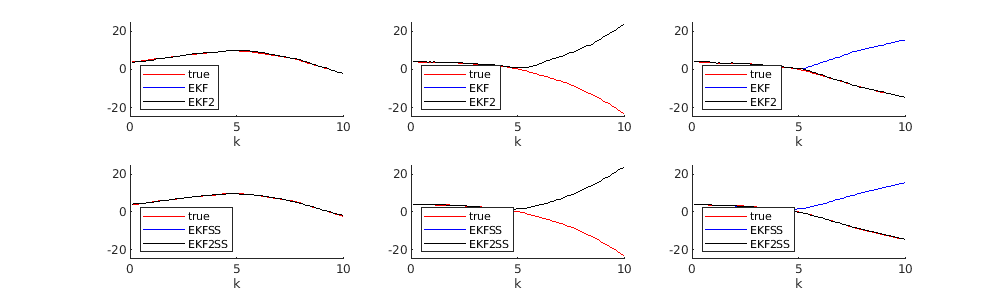

RMS error for filter 1 is 0.23342


RMS error for smoother 1 is 0.12749


RMS error for filter 2 is 0.23359


RMS error for smoother 2 is 0.12779


RMS error for filter 1 is 16.7545


RMS error for smoother 1 is 16.9733


RMS error for filter 2 is 16.7545


RMS error for smoother 2 is 16.9733


RMS error for filter 1 is 13.0564


RMS error for smoother 1 is 13.059


RMS error for filter 2 is 0.2282


RMS error for smoother 2 is 0.13058


figure; set(gcf,'position',[0 0 1000 300])
rng('default'); 
seeds=[0 12 23];
for ir=1:length(seeds)
   rng(seeds(ir));
   
   DT=0.1; nk=100; Qc=1; r=0.1; x0=[4;0];
   T=(1:nk)*DT; X=zeros(1,nk); Y=zeros(1,nk);
   Ak=[1,DT;0,1]; Qk=Qc*[DT^3/3,DT^2/2;DT^2/2,DT];
   x=x0;
   for k=1:nk
      x=mvnrnd(Ak*x,Qk)'; X(k)=x(1);
      Y(k)=norm([0.5-x(1);0.1])+sqrt(r)*randn;
   end
   
   
   m0=[4;0];    
   P0=0.01*eye(2);
   filtername={'EKF','EKF2'};
    GA={@GaussApproxEKF,@GaussApproxEKF2};
    nf=length(filtername);
    M1f=zeros(nf,nk);     M1s = zeros(nf,nk);
    Mf=zeros(2,nk); Pf=zeros(2,2,nk);   % save for the smoother
    for jf=1:nf
        m=m0; P=P0;
        for k=1:nk   % forward sweep (filter)
            [m,P]=gf_predict(m,P,@tracking_f,Q,GA{jf});
            [m,P]=gf_update(m,P,Y(k),@tracking_h,R,GA{jf});
            M1f(jf,k)=m(1);
            Mf(:,k)=m; Pf(:,:,k)=P;
        end
        rmse=sqrt(mean((X(1,:)-M1f(jf,:)).^2));
        disp(['RMS error for filter ' num2str(jf) ' is ' num2str(rmse)])
    
        M1s(jf,end)=m(1);
        for k=nk-1:-1:1  % backward sweep (smoother)
            [mp,Pp,Dk]=GA{jf}(Mf(:,k),Pf(:,:,k),@tracking_f,Q);
            Gk=Dk/Pp;
            m=Mf(:,k)+Gk*(m-mp);
            P=Pf(:,:,k)+Gk*(P-Pp)*Gk';
            M1s(jf,k)=m(1);
        end
        % one more backward step to estimate initial state
        [mp,Pp,D0]=GA{jf}(m0,P0,@tracking_f,Q); G0=D0/Pp;
        m=m0+G0*(m-mp); M1s0(jf)=m(1);
        rmse=sqrt(mean((X(1,:)-M1s(jf,:)).^2));
        disp(['RMS error for smoother ' num2str(jf) ' is ' num2str(rmse)])
   
    subplot(2,3,ir)
    plot(T,X,'r-',T,M1f(1,:),'b-',T,M1f(2,:),'k-')
    axis([0 T(end) -25 25]), box off,  xlabel('k')
    legend('true','EKF','EKF2','location','SW')
    
    subplot(2,3,ir+3)
    plot(T,X,'r-',T,M1s(1,:),'b-',T,M1s(2,:),'k-')
    axis([0 T(end) -25 25]), box off,  xlabel('k')
    legend('true','EKFSS','EKF2SS','location','SW')
    end
end


%seems that smoother works only if filtering converges to correct "path"
%and in this case smoother procudes good results

Problem 6:

Functions

function [M,P] = kf_predict(M,P,A,Q)
    %updates kalman filter M and P.
    M = A*M;
    P = A*P*A'+Q;
end

function [M,P] = kf_update(M,P,Y,H,R)
    % updates M and P given old M, old P, data Y,H and R
    S = H*P*H' + R;
    K = P*H'*inv(S);
    M = M + K*[Y-H*M];
    P = P-K*S*K';
end

function [mu,S,C]=GaussApproxEKF(m,P,g,E)
[mu,Gx]=g(m);
C=P*Gx';
S=Gx*C+E;
end

function [mu,S,C]=GaussApproxEKF2(m,P,g,E)
[mu,Gx,Gxx]=g(m);
C=P*Gx';
S=Gx*C+E;
n=size(E,1);
for i=1:n
    % GXX is a 3-dimensional array in the lecture; here it's a cell array
    mu(i)=mu(i)+0.5*trace(Gxx{i}*P);  
    for j=1:n
        S(i,j)=S(i,j)+0.5*trace(Gxx{i}*P*Gxx{j}*P);
    end
end
end

function [mu,S,C,X]=GaussApproxUKF(m,P,g,E)
nx=length(m);
alpha=1; beta=0; kappa=max(3-nx,1);
lambda=alpha^2*(nx+kappa)-nx;
WM=repmat(0.5/(nx+lambda),2*nx+1,1);
WM(1)=lambda/(nx+lambda);
WC=WM; WC(1)=lambda/(nx+lambda)+1-alpha^2+beta;
A=chol(P,'lower');   % use schol if P is singular
X=[m repmat(m,1,2*nx)+sqrt(lambda+nx)*[A -A]];
Y=g(X); ny=size(Y,1);
mu=zeros(ny,1); S=E; C=zeros(nx,ny);
for i=1:length(WM)
    mu=mu+WM(i)*Y(:,i);
end
for i=1:length(WC)
    S=S+WC(i)*(Y(:,i)- mu)*(Y(:,i) - mu)';
    C=C+WC(i)*(X(:,i)-m)*(Y(:,i) - mu)';
end
end

function [m,P]=gf_update(m,P,y,h,R,GaussApprox)
if ~isnan(y)
    [mu,S,C]=GaussApprox(m,P,h,R);
    K=C/S;
    P=P-K*S*K';
    m=m+K*(y-mu);
end
end

function [m,P]=gf_predict(m,P,f,Q,GaussApprox)
[m,P]=GaussApprox(m,P,f,Q);
end

function [f,Fx,Fxx]=pendulum_f(x)
DT=0.01; g=9.81;
f=x+DT*[ x(2)
    -g*sin(x(1))];
Fx=[1                DT
    -g*DT*cos(x(1))  1 ];
Fxx{1}=zeros(2,2);
Fxx{2}=[g*DT*sin(x(1)) 0
        0              0 ];
end

function [h,Hx,Hxx]=pendulum_h(x)
h=sin(x(1));
Hx=[cos(x(1)) 0];
Hxx{1}=[-sin(x(1))   0
          0          0];
end

%vectorized functions

function fval=pendulum_f_vectorized(x)
DT=0.01; g=9.81;
fval=x+DT*[ x(2,:)
    -g*sin(x(1,:))];
end

function hval=pendulum_h_vectorized(x)
hval=sin(x(1,:));
end

%problem 4 function

function [f,Fx,Fxx]=pendulum_f_leapfrog(x)
DT=0.01; g=9.81;
A = [1 DT;0 1];
f = A*x - [DT/2; 1]*g*DT*sin(x(1)+DT/2*x(2));
Fx = A - [DT/2,DT^2/4;1,DT/2]*g*DT*cos(x(1)+DT/2*x(2));
Fxx{2} = g*DT*sin(x(1)+DT/2*x(2))*[1,DT/2;DT/2,DT^2/4];
Fxx{1} = Fxx{2}*DT/2;
end

%problem 5 functions

function [fval,Fx,Fxx]=tracking_f(x)
DT = 0.1;
Fx = [1 DT; 0 1];
fval = Fx*x;
Fxx{1} = zeros(2,2);
Fxx{2} = zeros(2,2);
end

function [hval,Hx,Hxx]=tracking_h(x)
hval = norm([0.5-x(1);0.1]);   
Hx = [(x(1)-0.5)/hval 0];
Hxx{1} = [0.01/hval^3 0; 0 0];
end